# Path Planning and Tracking for Mobile Robot Pioneer P3DX

## 1. CoppeliaSim Initialization

disp('Program started');

Program started


sim=remApi('remoteApi'); % using the prototype file (remoteApiProto.m)

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


sim.simxFinish(-1); % just in case, close all opened connections
clientID=sim.simxStart('127.0.0.1',19997,true,true,5000,5);
if (clientID>-1)
    disp('Connected to remote API server');
    disp('Simulation ready');
    [~, right_motor] = sim.simxGetObjectHandle(clientID, '/PioneerP3DX[0]/rightMotor',sim.simx_opmode_blocking);
    [~, left_motor] = sim.simxGetObjectHandle(clientID,'/PioneerP3DX[0]/leftMotor',sim.simx_opmode_blocking);
    [~, pioneer_p3dx] = sim.simxGetObjectHandle(clientID,'/PioneerP3DX[0]',sim.simx_opmode_blocking);
    [~, bill] = sim.simxGetObjectHandle(clientID,'/Bill[4]',sim.simx_opmode_blocking);
    for i = 1:5
        [~, disc{i}] = sim.simxGetObjectHandle(clientID, ['/Disc[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end
    
    for i=1:1:16
        [~,sensor(i)]=sim.simxGetObjectHandle(clientID, ['/PioneerP3DX[0]/ultrasonicSensor[', num2str(i-1), ']'], sim.simx_opmode_blocking);
    end

    for i=1:1:16
        [~,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(clientID, sensor(i),sim.simx_opmode_streaming);
    end

    ret_codeR = sim.simxSetJointTargetVelocity(clientID, right_motor, 0.0, sim.simx_opmode_streaming);
    ret_codeL = sim.simxSetJointTargetVelocity(clientID, left_motor, 0.0, sim.simx_opmode_streaming);
    sim_run_flag = 1;
else
    disp('Simulation aborted')
    sim_run_flag = 0;
end

Connected to remote API server


Simulation ready


## 2. Path Planning

### Build Map

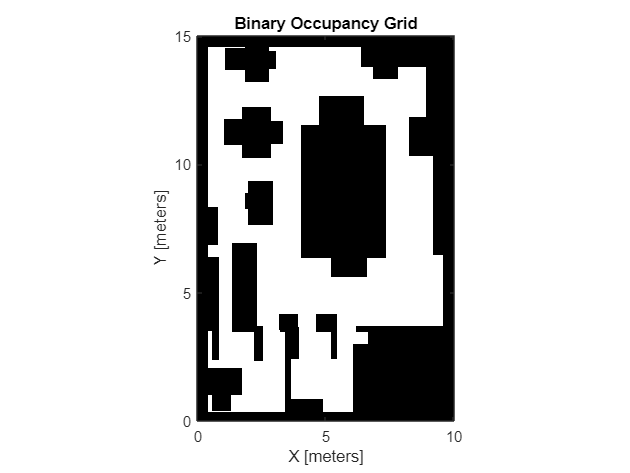

im_map = imread('Office-map.jpg');
im_bin = im2bw(im_map);
myMaplogical = not(logical(im_bin));
map = binaryOccupancyMap(myMaplogical,100);
show(map);

### Create Probabilistic Road Map (PRM)

PRM = mobileRobotPRM(map,300);
show(PRM);

### Find Path

if (sim_run_flag == 1)
    [~, pos]=sim.simxGetObjectPosition(clientID,pioneer_p3dx,-1,sim.simx_opmode_blocking);
    startPositionCoppelia = pos(1,1:2);
    targetGoal = 5
    for i = 1:targetGoal
        [~, room{i}]=sim.simxGetObjectPosition(clientID,disc{i},-1,sim.simx_opmode_blocking);
        roomPositionCoppelia{i} = room{i}(1,1:2);
    end

end

targetGoal = 5

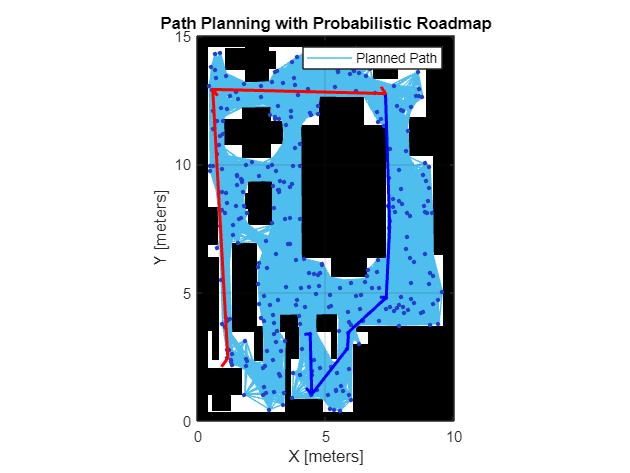

    4.1619    3.3658



if (startPositionCoppelia == roomPositionCoppelia{1})
    disp(startPositionCoppelia);
    disp('Localization failed');
    sim_run_flag = 0;
else
    % Robot to People
    disp(startPositionCoppelia);
    pathGoal{1} = findpath(PRM, double (startPositionCoppelia), double (roomPositionCoppelia{1}));
    pathGoal{2} = findpath(PRM, double (roomPositionCoppelia{1}), double (roomPositionCoppelia{2}));
    pathGoal{3} = findpath(PRM, double (roomPositionCoppelia{2}), double (roomPositionCoppelia{3}));
    
    % Gabungkan jalur-jalur menjadi satu
    paths = {pathGoal{1}, pathGoal{2}, pathGoal{3}};
    completePath = [];

    for i = 0:length(paths)-1
        if ~isempty(paths{i+1}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePath)
                completePath = paths{i+1};
            else
                completePath = [completePath; paths{i+1}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end
    % Robot to Homebase
    pathGoal{4} = findpath(PRM, double (roomPositionCoppelia{3}), double (roomPositionCoppelia{4}));
    pathGoal{5} = findpath(PRM, double (roomPositionCoppelia{4}), double (roomPositionCoppelia{5}));
    
    % Gabungkan jalur-jalur menjadi satu
    pathsHomebase = {pathGoal{4}, pathGoal{5}};
    completePathHomebase = [];

    for i = 1:length(pathsHomebase)
        if ~isempty(pathsHomebase{i}) % Adjusting index to access elements of the array
            % Gabungkan jalur, hindari duplikasi titik pertemuan
            if isempty(completePathHomebase)
                completePathHomebase = pathsHomebase{i};
            else
                completePathHomebase = [completePathHomebase; pathsHomebase{i}(2:end, :)];
            end
        else
            error(['No path found for segment ' num2str(i)]);
        end
    end

    %show(PRM);

    % Menambahkan plot jalur perencanaan pergerakan ke dalam grafik
    hold on;
    plot(completePath(:,1), completePath(:,2), 'b-', 'LineWidth', 2);
    plot(completePathHomebase(:,1), completePathHomebase(:,2), 'r-', 'LineWidth', 2);
    hold off;
    title('Path Planning with Probabilistic Roadmap');
    legend('Planned Path');
    grid on;
end

## 2. Path Tracking

if (sim_run_flag == 1)
    disp('Simulation is running');

####            Set the Pure Pursuit Control

    pp = controllerPurePursuit;

####            Init  goal reached status

    goalReachedCount = 0;
    reachedGoal = 0;
    count = 0;
    pathPlanning = 0;
    while goalReachedCount<3
        if(pathPlanning == 0)
            pp.Waypoints = completePath;
        end
        if(pathPlanning == 1)
            pp.Waypoints = completePathHomebase;
        end

####                   Get position and orientation of robot (Pose Sensing)

        [~, pos0]=sim.simxGetObjectPosition(clientID,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, ori]=sim.simxGetObjectOrientation(clientID,pioneer_p3dx,-1,sim.simx_opmode_blocking);
        [~, oriBill]=sim.simxGetObjectOrientation(clientID,bill,-1,sim.simx_opmode_blocking);
        currentPositionCoppelia = pos0(1,1:2);     
        currentOrientationCoppelia = ori(1,3);
        currentPoseCoppelia = [currentPositionCoppelia currentOrientationCoppelia];
        referenceOrientationPerson = oriBill(1,3); 

####                   Calculate the velocity of robot (Pure Pursuit)

        [v,w] = pp(currentPoseCoppelia);            

####                    Calculate the angular velocity for right and left wheel of robot (Inverse Kinematics)

        [phiR, phiL] = invkinem(v,w);

                    **Braitenberg Formula Calculation**

        point = [-1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1 -1];
        noDetectionDist=0.2;
        maxDetectionDist=0.1;
        detect=[0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
        braitenbergL=[-0.2 -0.4 -0.6 -0.8 -1.0 -1.2 -1.4 -1.6 0 0 0 0 0 0 0 0];
        braitenbergR=[-1.6 -1.4 -1.2 -1.0 -0.8 -0.6 -0.4 -0.2 0 0 0 0 0 0 0 0];
        
        for i=1:1:16
            [ret,detect(i),distance(i,:),~,~]=sim.simxReadProximitySensor(clientID, sensor(i),sim.simx_opmode_buffer);
            if(detect(i)==0)
                point(i)=1;
            else
                point(i)=norm(distance(i,:));
            end
        end

        for i=1:1:16
            distances=point(i);
            if(distances<noDetectionDist)
                if(distances<maxDetectionDist)
                    distances=maxDetectionDist;
                end
                    detect(i)=1-((distances-maxDetectionDist)/(noDetectionDist-maxDetectionDist));
            else
                detect(i)=0;
            end
        end

                    **Velocity Normalization**

        vnorm = 1.25;
        vmax = max(phiR, phiL);
        
        if(any(point < noDetectionDist))
            vright=vnorm + (braitenbergR(1)*detect(1)) + (braitenbergR(2)*detect(2)) + (braitenbergR(3)*detect(3)) + (braitenbergR(4)*detect(4)) + (braitenbergR(5)*detect(5)) + (braitenbergR(6)*detect(6)) + (braitenbergR(7)*detect(7)) + (braitenbergR(8)*detect(8));
            vleft=vnorm + (braitenbergL(1)*detect(1)) + (braitenbergL(2)*detect(2)) + (braitenbergL(3)*detect(3)) + (braitenbergL(4)*detect(4)) + (braitenbergL(5)*detect(5)) + (braitenbergL(6)*detect(6)) + (braitenbergL(7)*detect(7)) + (braitenbergL(8)*detect(8));    
            %This is the correct algorithm, 
            %but for some reason I try not to add up the Breitenberg constant and the detect variable
            %for i=1:16 
            %        vright=vnorm+braitenbergR(i)*detect(i);
            %        vleft=vnorm+braitenbergL(i)*detect(i);    
            %end
        else
            if vmax > vnorm
                vright = ((vnorm / vmax) * (phiR));
                vleft = ((vnorm / vmax) * (phiL));
            else
                vright = phiR;
                vleft = phiL
            end
        end
        

####                   Calculate the final angular velocity of robot wheels (Final Wheel Velocity Decision)

        goalPositionPeople = roomPositionCoppelia{3};
        distToGoalPeople = sqrt((currentPositionCoppelia(1)-goalPositionPeople(1))^2 + (currentPositionCoppelia(2)-goalPositionPeople(2))^2);

        goalPositionHomebase = roomPositionCoppelia{5};
        distToGoalHomebase = sqrt((currentPositionCoppelia(1)-goalPositionHomebase(1))^2 + (currentPositionCoppelia(2)-goalPositionHomebase(2))^2);
        
        if distToGoalPeople < 0.25 && pathPlanning == 0 
            vleft = 0.2 * (referenceOrientationPerson - currentOrientationCoppelia);
            vright = 0.2 * (referenceOrientationPerson + currentOrientationCoppelia);
            count = count+1;
        end
        
        if(count > 100)
            pathPlanning = 1;
        else
            pathPlanning = 0;
        end

        if distToGoalHomebase < 0.25 && pathPlanning == 1 
            vleft = 0;
            vright = 0;
        end
        
        velocity = [count, vleft, vright]
        disp(velocity);

####                   Send the final angular velocity of robot wheels to Pioneer P3DX  (Pioneer P3DX Robot)      

        ret_codeR = sim.simxSetJointTargetVelocity(clientID, right_motor, vright * 2, sim.simx_opmode_streaming);
        ret_codeL = sim.simxSetJointTargetVelocity(clientID, left_motor, vleft * 2, sim.simx_opmode_streaming);                        
    end 
    disp('Goal has been reached')
    sim.simxFinish(clientID);
end

Simulation is running


velocity =          0   -3.1487   -2.1650


         0   -3.1487   -2.1650



velocity =          0   -3.0188   -2.0290


         0   -3.0188   -2.0290



velocity =          0   -2.1754   -1.1246


         0   -2.1754   -1.1246



velocity =          0   -0.3248    0.1364


         0   -0.3248    0.1364



velocity =          0    0.6639    0.8953


         0    0.6639    0.8953



velocity =          0    0.8961    1.0614


         0    0.8961    1.0614



velocity =          0    0.1784    0.8100


         0    0.1784    0.8100



velocity =          0   -0.4047    0.5265


         0   -0.4047    0.5265



velocity =          0   -0.7099    0.3834


         0   -0.7099    0.3834



velocity =          0   -0.6743    0.4264


         0   -0.6743    0.4264



velocity =          0   -0.3444    0.6447


         0   -0.3444    0.6447



velocity =          0   -0.1957    0.7231


         0   -0.1957    0.7231



velocity =          0   -1.0040    0.6539


         0   -1.0040    0.6539



velocity =          0   -0.8989    0.7313


         0   -0.8989    0.7313



velocity =          0   -0.4439    0.9202


         0   -0.4439    0.9202



velocity =          0   -0.1605    0.9911


         0   -0.1605    0.9911



velocity =          0    0.1404    1.0661


         0    0.1404    1.0661



velocity =          0    0.4744    1.1483


         0    0.4744    1.1483



velocity =          0    0.6039    1.1692


         0    0.6039    1.1692



velocity =          0    0.7259    1.1845


         0    0.7259    1.1845



velocity =          0    0.8672    1.2022


         0    0.8672    1.2022



velocity =          0    1.0231    1.2216


         0    1.0231    1.2216



velocity =          0    1.1853    1.2419


         0    1.1853    1.2419



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity =          0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3 single row vector
         0    1.2500    0.4917


         0    1.2500    0.4917



velocity = 1×3 single row vector
         0    1.2500    0.4689


         0    1.2500    0.4689



velocity = 1×3 single row vector
         0    1.2500    0.6725


         0    1.2500    0.6725



vleft = single
1.0982

velocity = 1×3 single row vector
         0    1.0982    0.9530


         0    1.0982    0.9530



vleft = single
0.9349

velocity = 1×3 single row vector
         0    0.9349    1.1163


         0    0.9349    1.1163



vleft = single
0.9171

velocity = 1×3 single row vector
         0    0.9171    1.1342


         0    0.9171    1.1342



vleft = single
0.9947

velocity = 1×3 single row vector
         0    0.9947    1.0565


         0    0.9947    1.0565



vleft = single
1.0650

velocity = 1×3 single row vector
         0    1.0650    0.9863


         0    1.0650    0.9863



vleft = single
1.0837

velocity = 1×3 single row vector
         0    1.0837    0.9676


         0    1.0837    0.9676



vleft = single
1.0643

velocity = 1×3 single row vector
         0    1.0643    0.9870


         0    1.0643    0.9870



vleft = single
1.0400

velocity = 1×3 single row vector
         0    1.0400    1.0112


         0    1.0400    1.0112



vleft = single
1.0301

velocity = 1×3 single row vector
         0    1.0301    1.0212


         0    1.0301    1.0212



vleft = single
1.0328

velocity = 1×3 single row vector
         0    1.0328    1.0185


         0    1.0328    1.0185



vleft = single
1.0389

velocity = 1×3 single row vector
         0    1.0389    1.0124


         0    1.0389    1.0124



vleft = single
1.0423

velocity = 1×3 single row vector
         0    1.0423    1.0089


         0    1.0423    1.0089



vleft = single
1.0418

velocity = 1×3 single row vector
         0    1.0418    1.0094


         0    1.0418    1.0094



vleft = single
1.0396

velocity = 1×3 single row vector
         0    1.0396    1.0116


         0    1.0396    1.0116



vleft = single
1.0379

velocity = 1×3 single row vector
         0    1.0379    1.0133


         0    1.0379    1.0133



vleft = single
1.0373

velocity = 1×3 single row vector
         0    1.0373    1.0140


         0    1.0373    1.0140



vleft = single
1.0372

velocity = 1×3 single row vector
         0    1.0372    1.0141


         0    1.0372    1.0141



vleft = single
1.0372

velocity = 1×3 single row vector
         0    1.0372    1.0141


         0    1.0372    1.0141



vleft = single
1.0369

velocity = 1×3
         0    1.0369    1.0144


         0    1.0369    1.0144



vleft = single
1.0366

velocity = 1×3
         0    1.0366    1.0147


         0    1.0366    1.0147



vleft = single
1.0362

velocity = 1×3
         0    1.0362    1.0151


         0    1.0362    1.0151



vleft = single
1.0358

velocity = 1×3
         0    1.0358    1.0155


         0    1.0358    1.0155



vleft = single
1.0354

velocity = 1×3
         0    1.0354    1.0159


         0    1.0354    1.0159



vleft = single
1.0351

velocity = 1×3
         0    1.0351    1.0162


         0    1.0351    1.0162



vleft = single
1.0348

velocity = 1×3
         0    1.0348    1.0164


         0    1.0348    1.0164



vleft = single
1.0346

velocity = 1×3
         0    1.0346    1.0167


         0    1.0346    1.0167



vleft = single
1.0343

velocity = 1×3
         0    1.0343    1.0169


         0    1.0343    1.0169



vleft = single
1.0340

velocity = 1×3
         0    1.0340    1.0172


         0    1.0340    1.0172



vleft = single
1.0337

velocity = 1×3
         0    1.0337    1.0176


         0    1.0337    1.0176



vleft = single
1.0335

velocity = 1×3
         0    1.0335    1.0178


         0    1.0335    1.0178



vleft = single
1.0333

velocity = 1×3
         0    1.0333    1.0180


         0    1.0333    1.0180



vleft = single
1.0952

velocity = 1×3
         0    1.0952    0.9561


         0    1.0952    0.9561



vleft = single
1.1639

velocity = 1×3
         0    1.1639    0.8873


         0    1.1639    0.8873



vleft = single
1.1987

velocity = 1×3
         0    1.1987    0.8526


         0    1.1987    0.8526



vleft = single
1.2025

velocity = 1×3
         0    1.2025    0.8488


         0    1.2025    0.8488



vleft = single
1.2006

velocity = 1×3
         0    1.2006    0.8507


         0    1.2006    0.8507



vleft = single
1.2098

velocity = 1×3
         0    1.2098    0.8415


         0    1.2098    0.8415



vleft = single
1.2332

velocity = 1×3
         0    1.2332    0.8181


         0    1.2332    0.8181



velocity = 1×3
         0    1.2500    0.7775


         0    1.2500    0.7775



velocity = 1×3
         0    1.2500    0.7221


         0    1.2500    0.7221



velocity = 1×3
         0    1.2500    0.6662


         0    1.2500    0.6662



velocity = 1×3
         0    1.2500    0.6107


         0    1.2500    0.6107



vleft = single
1.2146

velocity = 1×3
         0    1.2146    0.8367


         0    1.2146    0.8367



vleft = single
0.8325

velocity = 1×3
         0    0.8325    1.2188


         0    0.8325    1.2188



velocity = 1×3
         0    0.2857    1.2500


         0    0.2857    1.2500



velocity = 1×3
         0    0.1621    1.2500


         0    0.1621    1.2500



velocity = 1×3
         0    0.2005    1.2500


         0    0.2005    1.2500



velocity = 1×3
         0    0.3012    1.2500


         0    0.3012    1.2500



velocity = 1×3
         0    0.4018    1.2500


         0    0.4018    1.2500



velocity = 1×3
         0    0.4764    1.2500


         0    0.4764    1.2500



velocity = 1×3
         0    0.5235    1.2500


         0    0.5235    1.2500



velocity = 1×3
         0    0.5641    1.2500


         0    0.5641    1.2500



velocity = 1×3
         0    0.6000    1.2500


         0    0.6000    1.2500



velocity = 1×3
         0    0.6250    1.2500


         0    0.6250    1.2500



velocity = 1×3
         0    0.6740    1.2500


         0    0.6740    1.2500



velocity = 1×3
         0    0.6338    1.2500


         0    0.6338    1.2500



velocity = 1×3
         0    0.4091    1.2500


         0    0.4091    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0    0.4217    1.2500


         0    0.4217    1.2500



velocity = 1×3
         0    0.6093    1.2500


         0    0.6093    1.2500



velocity = 1×3
         0    0.6725    1.2500


         0    0.6725    1.2500



velocity = 1×3
         0    0.6793    1.2500


         0    0.6793    1.2500



velocity = 1×3
         0    0.6998    1.2500


         0    0.6998    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3459    1.2500


         0   -0.3459    1.2500



velocity = 1×3
         0   -0.1889    1.2500


         0   -0.1889    1.2500



velocity = 1×3
         0    0.0357    1.2500


         0    0.0357    1.2500



velocity = 1×3
         0    0.3462    1.2500


         0    0.3462    1.2500



velocity = 1×3
         0    0.7642    1.2500


         0    0.7642    1.2500



vleft = single
1.0261

velocity = 1×3
         0    1.0261    1.0251


         0    1.0261    1.0251



vleft = single
1.1653

velocity = 1×3
         0    1.1653    0.8860


         0    1.1653    0.8860



vleft = single
1.1490

velocity = 1×3
         0    1.1490    0.9023


         0    1.1490    0.9023



vleft = single
1.0635

velocity = 1×3
         0    1.0635    0.9878


         0    1.0635    0.9878



vleft = single
0.9987

velocity = 1×3
         0    0.9987    1.0526


         0    0.9987    1.0526



vleft = single
0.9900

velocity = 1×3
         0    0.9900    1.0613


         0    0.9900    1.0613



vleft = single
1.0153

velocity = 1×3
         0    1.0153    1.0359


         0    1.0153    1.0359



vleft = single
1.0396

velocity = 1×3
         0    1.0396    1.0117


         0    1.0396    1.0117



vleft = single
1.0468

velocity = 1×3
         0    1.0468    1.0044


         0    1.0468    1.0044



vleft = single
1.0405

velocity = 1×3
         0    1.0405    1.0108


         0    1.0405    1.0108



vleft = single
1.0317

velocity = 1×3
         0    1.0317    1.0196


         0    1.0317    1.0196



vleft = single
1.0275

velocity = 1×3
         0    1.0275    1.0238


         0    1.0275    1.0238



velocity = 1×3
         0    0.7055    1.2500


         0    0.7055    1.2500



velocity = 1×3
         0    0.5989    1.2500


         0    0.5989    1.2500



velocity = 1×3
         0    0.4794    1.2500


         0    0.4794    1.2500



velocity = 1×3
         0    0.6795    1.2500


         0    0.6795    1.2500



vleft = single
0.9066

velocity = 1×3
         0    0.9066    1.1447


         0    0.9066    1.1447



vleft = single
1.0109

velocity = 1×3
         0    1.0109    1.0404


         0    1.0109    1.0404



vleft = single
1.0212

velocity = 1×3
         0    1.0212    1.0301


         0    1.0212    1.0301



velocity = 1×3
         0   -1.7261    0.6530


         0   -1.7261    0.6530



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500    1.2500


         0    1.2500    1.2500



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3524


         0    1.2500   -0.3524



velocity = 1×3
         0    0.1146    1.2500


         0    0.1146    1.2500



velocity = 1×3
         0    1.2500    0.2652


         0    1.2500    0.2652



velocity = 1×3
         0    0.1499    1.2500


         0    0.1499    1.2500



velocity = 1×3
         0    0.0769    1.2500


         0    0.0769    1.2500



velocity = 1×3
         0    0.1562    1.2500


         0    0.1562    1.2500



velocity = 1×3
         0    0.4377    1.2500


         0    0.4377    1.2500



vleft = single
0.8679

velocity = 1×3
         0    0.8679    1.1834


         0    0.8679    1.1834



vleft = single
1.0288

velocity = 1×3
         0    1.0288    1.0225


         0    1.0288    1.0225



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3894    1.2500


         0   -0.3894    1.2500



velocity = 1×3
         0   -0.3154    1.2500


         0   -0.3154    1.2500



velocity = 1×3
         0   -0.1313    1.2500


         0   -0.1313    1.2500



velocity = 1×3
         0    0.1242    1.2500


         0    0.1242    1.2500



velocity = 1×3
         0    0.4822    1.2500


         0    0.4822    1.2500



vleft = single
0.8851

velocity = 1×3
         0    0.8851    1.1662


         0    0.8851    1.1662



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



velocity = 1×3
         0    1.2500   -0.3894


         0    1.2500   -0.3894



sim.delete(); % call the destructor! 
if (sim_run_flag == 1)
    beep;
    disp('Simulation successful');
else
    beep;pause(1);beep;
    disp('Simulation unsuccessful');
end
disp('Program ended');  

## Functions Definition

function [pR,pL] = invkinem(v,w)
% INVKINEM Inverse kinematics for Pioneer P3DX Diffrerential Steering Robot
    wheelradius = 0.195/2;
    bodywidth = 0.381;
    R2 = wheelradius/2;
    RB = wheelradius/bodywidth;
    vw = [v;w];
    kinemat = [R2 R2; RB -RB];
    pLR = kinemat\vw;
    pR = pLR(1);
    pL = pLR(2);
end